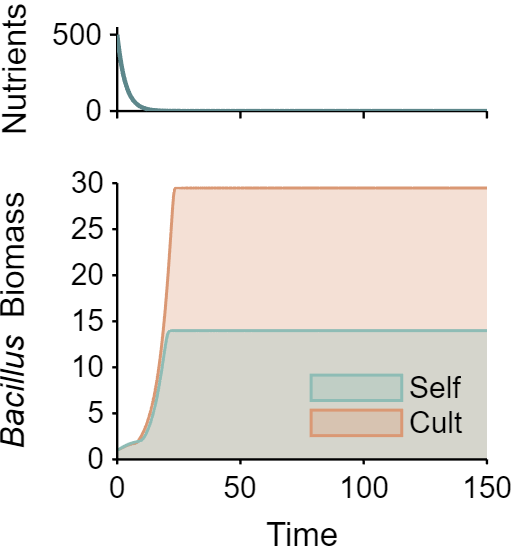

% =========================================================================
% Section 1: Data Calculation
% =========================================================================
% Parameter settings
tspan = [0 150]; % Time range

% Define ODE system (without nutrient decay)
ode = @(t, y) -0.3*y;

% Initial conditions
initial_conditions = 500;

% Solve using ode15s
[t, y] = ode15s(ode, tspan, initial_conditions);

% =========================================================================
% Section 2: Cell Journal Style Plotting
% =========================================================================

% --- 1. Create figure window ---
% Requirements: Width 6 cm, Height 6.5 cm, Background set to pure white
fig = figure('Units', 'centimeters', 'Position', [10, 10, 6, 6.5], 'Color', 'w');

% --- 2. Precise space allocation (normalized units) ---
% Margins allocated for 10pt font padding:
% Bottom margin 17%, top margin 5%, middle gap 5%, with left/right padding for labels.
pos_top    = [0.23, 0.80, 0.72, 0.15]; % [left, bottom, width, height]
pos_bottom = [0.23, 0.17, 0.72, 0.50];

% ==================== Plot Top Subplot ====================
ax1 = axes('Position', pos_top);

% Deep cyan-gray line (Cell journal style), LineWidth = 1.5 pt
plot(ax1, t, y, 'Color', "#5D878B", 'LineWidth', 1.5);

% Set axis labels (Font size 10 pt, Arial)
ylabel(ax1, 'Nutrients', 'FontSize', 10, 'FontName', 'Arial');

% Set axis limits and formatting
xlim(ax1, [0 150]);
ylim(ax1, [0 550]);
set(ax1, ...
    'FontSize', 10, ...
    'FontName', 'Arial', ...
    'Box', 'off', ...
    'TickDir', 'out', ...
    'LineWidth', 0.8, ...      % Axis line width
    'XColor', 'k', 'YColor', 'k', ...
    'XTickLabel', [], ...      % Hide X-tick labels for compact layout
    'TickLength', [0.03, 0.03]);

% ==========================================
% Section 3: Parameter Settings & Simulation
% ==========================================
a = 1.1;
params.K_BN = 250;      
params.K_HN = 50;      
params.K_HM = 30;      
params.Y_B = 0.5;        
params.Y_HN = 0.5;     
params.Y_HM = 1;       
params.delta_N = 0.3;  
params.alpha = 5;
params.gamma = 0.1;
params.Ncrit = 20;     
params.h = 8;   
params.mu_B = 0.2; 
params.mu_H = 1;   
params.delta_A = 0.1;
params.K_BD = 1;
params.K_CD = 1;
params.epsilon = 0.6;
params.kappa = 2;
params.Y_BD = 1;
params.Y_CD = 1;

% ---------------------------------------------------------
% Additional parameters needed after adding C (set similar to H)
% ---------------------------------------------------------

% [Growth Rate Parameters]
params.mu_C = 0.3; % Set according to your actual mu_H

% [Half-Saturation Constants (Monod constants)]
params.K_CN = 50;  % Half-saturation constant of C for N
params.K_CM = 30;  % Half-saturation constant of C for M

% [Yield Coefficients]
params.Y_CN = 0.5;   % Yield coefficient of C from N
params.Y_CM = 1;     % Yield coefficient of C from M

% [Interaction / Mortality Parameters]
% If B can kill C: use these two parameters;
% If B cannot kill C: set both parameters to 0.
params.kappa_C = 2;      % Killing rate constant of antimicrobial A on C
params.epsilon_C = 0.6;  % Conversion efficiency of dead C into debris D

% Initial conditions and time span
N0 = 500; B0 = 1; M0 = 10; H0=5;
tspan = [0 150];
y0_co = [N0; B0; H0; M0; 0; 0; 1];

% Solve ODE for co-culture
[t, y] = ode15s(@(t, y) B_H_C_model_killable(t, y, params), tspan, y0_co);
tt = t;
B = y(:,2);

% Modify growth rate of B for mono-culture / Self strategy
params.mu_B = params.mu_B * a;
params.alpha = 0;
y0_mono = [N0; B0; H0; M0; 0; 0; 1]; 

% Solve ODE for mono-culture
[t, y] = ode15s(@(t, y) B_H_C_model_killable(t, y, params), tspan, y0_mono);

% ==================== Plot Bottom Subplot ====================
ax2 = axes('Position', pos_bottom);

% Plot area graphs (LineWidth = 1 pt)
p1 = area(ax2, tt, B, 'LineStyle','-','LineWidth', 1, ...
    'FaceColor', '#DA9874', 'FaceAlpha', 0.3, 'EdgeColor', '#DA9874'); 
hold(ax2, 'on');
p2 = area(ax2, t, y(:,2), 'LineStyle','-', 'LineWidth', 1, ...
    'FaceColor', '#8EBCB5', 'FaceAlpha', 0.3, 'EdgeColor', '#8EBCB5');

xlim(ax2, [0 150]);
ylim(ax2, [0 30]);
set(ax2, 'YTick', 0:5:30); % Set Y-ticks from 0 to 30

% Set axis labels (Font size 10 pt, Arial)
xlabel(ax2, 'Time', 'FontSize', 10, 'FontName', 'Arial');
yl2 = ylabel(ax2, '{\itBacillus} Biomass', 'FontSize', 10, 'FontName', 'Arial');

% Legend formatting (No border, 10 pt Arial)
lgd = legend(ax2, 'Cult', 'Self'); 
set(lgd, 'FontSize', 10, 'FontName', 'Arial', 'Box', 'off', 'Location', 'southeast');

% Axis formatting for bottom subplot
set(ax2, ...
    'FontSize', 10, ...
    'FontName', 'Arial', ...
    'Box', 'off', ...
    'TickDir', 'out', ...
    'LineWidth', 0.8, ...
    'XColor', 'k', 'YColor', 'k', ...
    'TickLength', [0.02, 0.02]);

% ==================== Force Y-axis Label Alignment ====================
% 1. Convert units to normalized (0 to 1)
set(yl2, 'Units', 'Normalized');

% 2. Force identical negative X position relative to left axis edge
% -0.22 offset, 0.5 Y-center, 0 Z-plane
label_x_position = -0.22; 
set(yl2, 'Position', [label_x_position, 0.5, 0]);

exportgraphics(fig, 'Panel_13_14.pdf', 'ContentType', 'vector');
saveas(fig, 'Panel_13_14.emf');


function dydt = B_H_C_model_killable(~, y, params)
    N = y(1); B = y(2); H = y(3); M = y(4); A = y(5); D = y(6); C = y(7);
    
    % --- Existing Monod terms ---
    monod_B = N / (params.K_BN + N);
    monod_H_N = N / (params.K_HN + N);
    monod_H_M = M / (params.K_HM + M);
    monod_B_D = D / (params.K_BD + D);
    
    % --- Additional Monod terms for C ---
    monod_C_N = N / (params.K_CN + N);
    monod_C_M = M / (params.K_CM + M);
    monod_C_D = D / (params.K_CD + D);

    % --- Growth rates ---
    growth_B_N = params.mu_B * monod_B * B;
    growth_H = params.mu_H * monod_H_N * monod_H_M * H;
    growth_B_D = params.mu_B * monod_B_D * B;
    
    growth_C_basal = params.mu_C * monod_C_N * C;
    growth_C_enhance = params.mu_C * monod_C_N * monod_C_M * C;
    total_growth_C = growth_C_basal + growth_C_enhance;
    growth_C_D = params.mu_C * monod_C_D * C;

    % Hill activation function
    hill_activate = (N^params.h) / (params.Ncrit^params.h + N^params.h);
    
    % --- Equations ---
    % N is consumed by B, H, and C (both pathways consume N)
    dNdt = - (1/params.Y_B)*growth_B_N - (1/params.Y_HN)*growth_H - (1/params.Y_CN)*total_growth_C - params.delta_N*N;
    
    dBdt = growth_B_N + growth_B_D;
    
    dHdt = growth_H - params.kappa * A * H;
    
    % M is consumed by H and C (only the accelerated pathway consumes M)
    dMdt = params.alpha * hill_activate * B - (1/params.Y_HM) * growth_H - (1/params.Y_CM) * growth_C_enhance;
    
    dAdt = params.gamma * (1-hill_activate) * B  - params.delta_A * A;
    
    % Sources for D include killed C
    dDdt = params.epsilon * params.kappa * A * H + params.epsilon_C * params.kappa_C * A * C - (1/params.Y_BD)*growth_B_D - (1/params.Y_CD)*growth_C_D;
    
    % Dynamics of C: growth minus killing by A
    dCdt = total_growth_C + growth_C_D - params.kappa_C * A * C;
    
    dydt = [dNdt; dBdt; dHdt; dMdt; dAdt; dDdt; dCdt];
end